## Testing the kinematic model

knms = KineMod();

Creating valid position as starting position

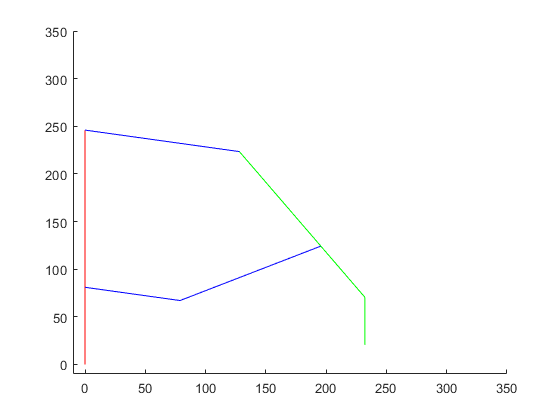

pos1 = ArmPos();
X = -10;
Z = -10;
pos1.phiX = X/360 * 2 * pi;
pos1.phiZ = Z/360 * 2 * pi;
pos1 = pos1.phiZXtoFullpos(false);

pos1.draw();

### Creating copy of position and moving end effector

dr = -10

dr = -10

dz = 10

dz = 10

pos2 = pos1;
pos2.C = pos2.C + [dr,dz];
pos2 = pos2.setD;
%pos2.draw();
pos2.validate(false); %should return as invalid position

### Computing new possible solutions

tic
r1 = knms.CtoA(pos2);
r2 = knms.BtoE(r1);

ans = 2

toc

Elapsed time is 0.011531 seconds.


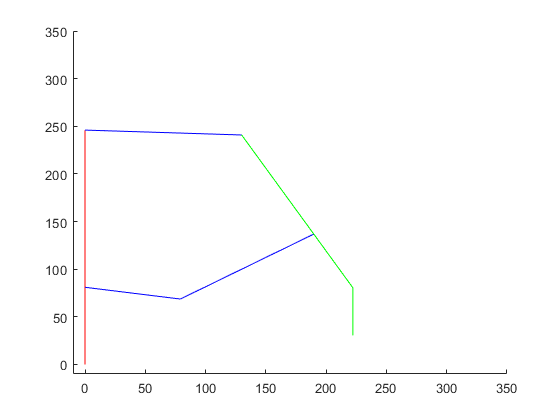

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [129.8987 240.8680]
          B: [189.7323 136.8491]
          C: [222.1423 80.5055]
          D: [222.1423 30.5055]
          E: [79.0444 68.6716]
       phiX: -0.1547
       phiZ: -0.0395
       phi1: 0.7068


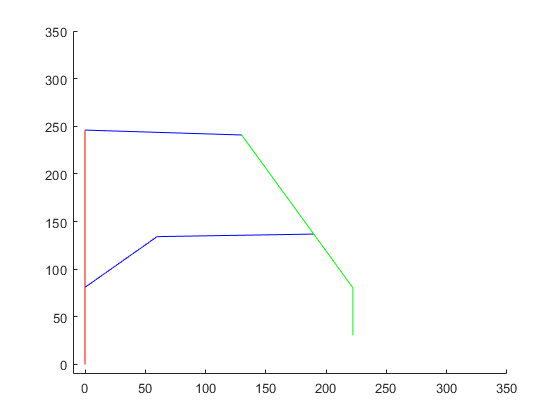

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [129.8987 240.8680]
          B: [189.7323 136.8491]
          C: [222.1423 80.5055]
          D: [222.1423 30.5055]
          E: [59.7596 134.1864]
       phiX: 0.7273
       phiZ: -0.0395
       phi1: -0.7068



for i=1:length(r2)
    r2(i).draw()
end

knms.kinDist(pos1,r2)

ans =    33.0235  101.1627


knms.negativePhi1(r2)

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [129.8987 240.8680]
          B: [189.7323 136.8491]
          C: [222.1423 80.5055]
          D: [222.1423 30.5055]
          E: [59.7596 134.1864]
       phiX: 0.7273
       phiZ: -0.0395
       phi1: -0.7068


x = ArmPos();
j = 0;
r_start =0;
r_end = 400;
z_start = 0;
z_end = 220;
tic
failuremap = zeros(z_start-z_end+1,r_end-r_start+1);
for r=r_start:r_end
    for z=z_start:z_end

        x.C = [r,z];
        [r1, error1] = knms.CtoA(x);
        if error1
            failuremap(z-z_start+1,r-r_start+1)  = 1;
            continue
        end
        [r2, error2] = knms.BtoE(r1);
        if error2
            failuremap(z-z_start+1,r-r_start+1)  = 1;
            continue
        end
        j = j + 1;
        failuremap(z-z_start+1,r-r_start+1) = 0;
        result(z-z_start+1,r-r_start+1) = knms.negativePhi1(r2);
    end
    
end
toc

Elapsed time is 11.279251 seconds.


j

j = 21387


failuremap

failuremap =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1

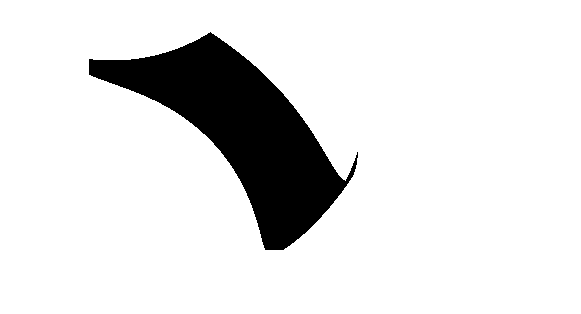


figure()
clf
imshow(flipud(failuremap))

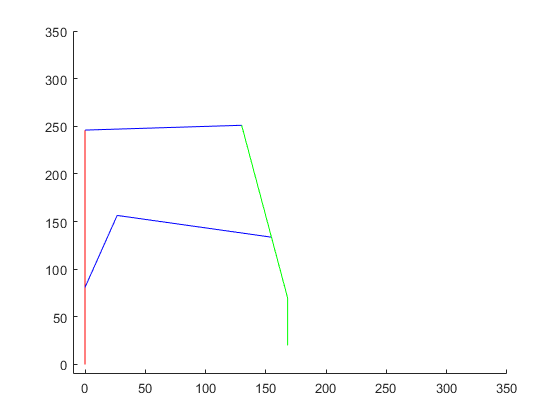


result(69,31).draw();

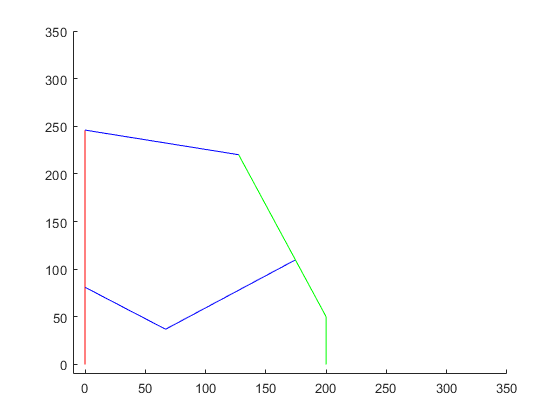

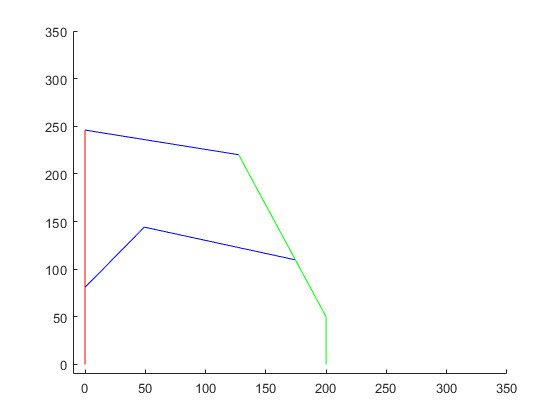

r2 =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [127.4065 220.1622]
          B: [174.4942 109.7867]
          C: [200 50]
          D: [200 0]
          E: [49.1172 144.1467]
       phiX: 0.9097
       phiZ: -0.2001
       phi1: -1.1772


error2 = logical
   0


x = ArmPos();
x.C = [200,50];
[r1, error1] = knms.CtoA(x);
[r2, error2] = knms.BtoE(r1)

tic
y = knms.IK_MAU([200,50],true)

y =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [127.4065 220.1622]
          B: [174.4942 109.7867]
          C: [200 50]
          D: [200 0]
          E: [49.1172 144.1467]
       phiX: 0.9097
       phiZ: -0.2001
       phi1: -1.1772


toc

Elapsed time is 0.010309 seconds.


ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [127.4065 220.1622]
          B: [174.4942 109.7867]
          C: [200 50]
          D: [200 0]
          E: [49.1172 144.1467]
       phiX: 0.9097
       phiZ: -0.2001
       phi1: -1.1772


y.draw()